Introduction to Control Systems - Simulation

## 1.2 First-Order Systems

clear sim
tank_sim = sim('ME419_Ex1_2.slx') ;
max_TD = max(tank_sim.Tank_Drop); % Maximum Tank Drop

max_TD = 0.4999

Tau_TD = 0.632*max_TD; % Tank Level at 63.2% which is 1 Tau

Tau_TD = 0.3160

index = find(tank_sim.Tank_Drop>=Tau_TD-Tau_TD*0.05 & tank_sim.Tank_Drop<=Tau_TD+Tau_TD*0.05); % index of the time constant

index = 26

Time_Const = tank_sim.tout(index);

Time_Const = 1.9942

### Diagrams

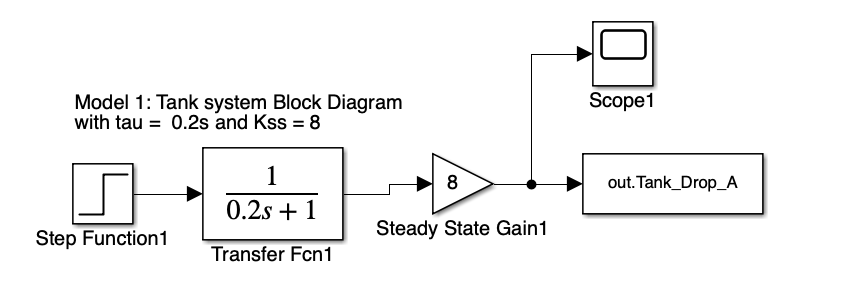

Figure 1.2.1: Model A water tank system diagram 

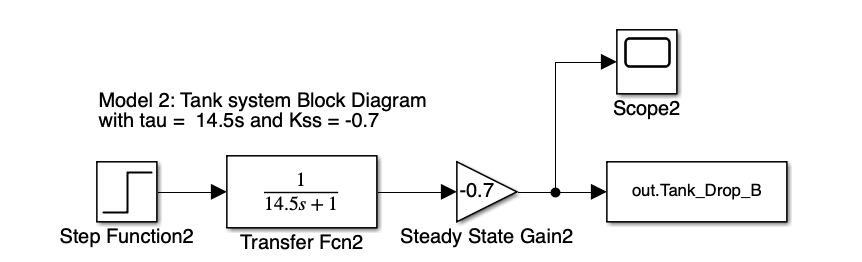

Figure 1.2.2: Model B water tank system diagram 

### Plots

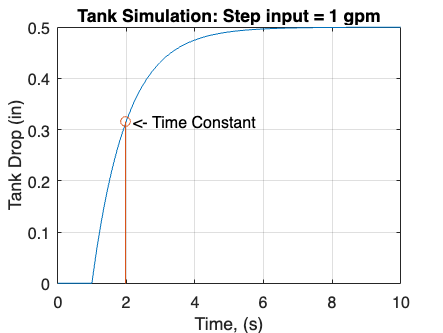

figure()
plot(tank_sim.tout, tank_sim.Tank_Drop)
title('Tank Simulation: Step input = 1 gpm')
xlabel('Time, (s)')
ylabel('Tank Drop (in)')
grid on
hold on
stem(Time_Const,tank_sim.Tank_Drop(index))
text(2.2,0.317,'<- Time Constant')
hold off

#### System 1.2A

Tau_A = 0.8/4;
max_TD_A = max(tank_sim.Tank_Drop_A); % Maximum Tank Drop
Tau_TD_A = 0.632*max_TD_A; % Tank Level at 63.2% which is 1 Tau
index_A = find(tank_sim.Tank_Drop_A>=Tau_TD_A-Tau_TD_A*0.05 & tank_sim.Tank_Drop_A<=Tau_TD_A+Tau_TD_A*0.05)

index_A = 14

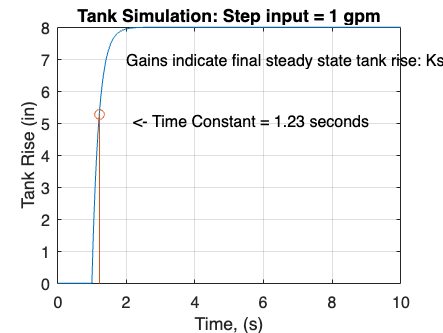

Time_Const_A = tank_sim.tout(index_A);

figure()
plot(tank_sim.tout, tank_sim.Tank_Drop_A)
title('Tank Simulation: Step input = 1 gpm')
xlabel('Time, (s)')
ylabel('Tank Rise (in)')
grid on
hold on
stem(Time_Const_A,tank_sim.Tank_Drop_A(index_A))
text(2.2,5.1,'<- Time Constant = 1.23 seconds')
text(2,7,'Gains indicate final steady state tank rise: Kss= 8')
hold off

#### System 1.2B

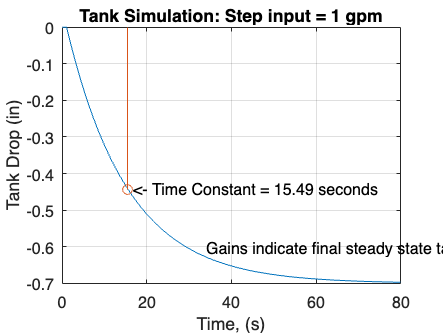

clear sim
t = 80 ; % Defined Time Span
tank_sim = sim('ME419_Ex1_2.slx',t) ;

Settle_T_B = 58 ; % Settling Time of System (4Tau)
Tau_A = Settle_T_B/4; % Time Constant

max_TD_B = min(tank_sim.Tank_Drop_B); % Maximum Tank Drop
Tau_TD_B = 0.632*max_TD_B; % Tank Level at 63.2% which is 1 Tau
index_B = find(tank_sim.Tank_Drop_B<=Tau_TD_B-Tau_TD_B*0.02 & tank_sim.Tank_Drop_B>=Tau_TD_B+Tau_TD_B*0.02);
Time_Const_B = tank_sim.tout(index_B);
figure()
plot(tank_sim.tout, tank_sim.Tank_Drop_B)
title('Tank Simulation: Step input = 1 gpm')
xlabel('Time, (s)')
ylabel('Tank Drop (in)')
grid on
hold on
stem(Time_Const_B,tank_sim.Tank_Drop_B(index_B))
text(16.6,-0.44,'<- Time Constant = 15.49 seconds')
text(34,-0.6,'Gains indicate final steady state tank drop: Kss= -0.7')
hold off

### Questions

*(a) Does the system behave as expected?*

We expected the system to reach the final value of 0.5 inches in a non linear way, similar to a DC motor response which is what we

observed here.

*(b) How long does the system take to reach 63.2% of its final value?*

The sytema reaches 63.2% of its final value at a time of two seconds

*(c) What was the size of the input step?*

The input step is the flowrate and we used a unit step function that goes from 0 to 1 gal/min. 

(d) What size output change did it produce?

The step response approaches 0.5 inches. 

(e) How could you change the system to produce in the same time frame a steady state responce that is twice as great as the step input?

Either change step input final value to double initial value or change gain to double its initial value. 

## 1.3 Second-Order Systems

clear sim
%t = 80 ; % Defined Time Span
mass_damper_sim = sim('ME419_EX1_3.slx') ;
Kss_A = 3;
freq_A = 1; %hz
Wn_A = freq_A*2*pi;
zeta_A = 0.15;
Wd_A = Wn_A*sqrt(1-zeta_A^2);

Kss_B = 3; %steady state gain
freq_B = 1; % hz
Wn_B = freq_B*2*pi; % natural frequency
zeta_B = 0.15*2; % damping ratio
Wd_B = Wn_B*sqrt(1-zeta_B^2); % damping frequency
Kss_C = 3;
freq_C = 1*2; %hz
Wn_C = freq_C*2*pi;
zeta_C = 0.15;
Wd_C = Wn_C*sqrt(1-zeta_C^2);

### Model A Parameters

% checks that the steady state values before and after the step response
% are as expected
ss_change_A = mass_damper_sim.A;
check_ss_gain_A = round((ss_change_A(end)-ss_change_A(1))/1) % checks that the plot agrees with Kss = 3

check_ss_gain_A = 3


% Compares that the simulated and calculated %OS are the similar
percOS_A = exp(-zeta_A*pi/sqrt(1-zeta_A^2));
dataOS_A = (max(ss_change_A)-3)/3;

disp("Calculated Overshoot")

Calculated Overshoot


disp(percOS_A)

    0.6209



disp("Simulated Overshoot")

Simulated Overshoot


disp(dataOS_A)

    0.6208




% this block of code finds the first and second peaks on the graph in order
% to find the damping frequency
check_osc = ss_change_A(islocalmax(ss_change_A)~=0); % finds the local maximums of the plot
val1 = find(check_osc(1) == ss_change_A);
val2 = find(check_osc(2) == ss_change_A);
data_damping_freq = 2*pi/(mass_damper_sim.tout(val2) - mass_damper_sim.tout(val1));

disp('calculated damping frequency in rad/s:')

calculated damping frequency in rad/s:


disp(Wd_A)

    6.2121



disp('damping frequency from plot in rad/s:')

damping frequency from plot in rad/s:


disp(data_damping_freq)

    6.2065



### Model B Parameters

Doubling the damping ratio should decrease the OS percentage.

ss_change_B = mass_damper_sim.A1;
percOS_B = exp(-zeta_B*pi/sqrt(1-zeta_B^2))

percOS_B = 0.3723

dataOS_B = (max(ss_change_B)-3)/3

dataOS_B = 0.3723

### Model C Parameters

Doubling the oscilllation frequency should increase speed at which the system reaches steady state. This should be the case because the system should lose energy more rapidly due the the faster oscillations

ss_change_C = mass_damper_sim.A2;
check_osc = ss_change_C(islocalmax(ss_change_C)~=0);
val1 = find(check_osc(1) == ss_change_C);
val2 = find(check_osc(2) == ss_change_C);
data_damping_freq = 2*pi/(mass_damper_sim.tout(val2) - mass_damper_sim.tout(val1))

data_damping_freq = 12.2320

### Plots

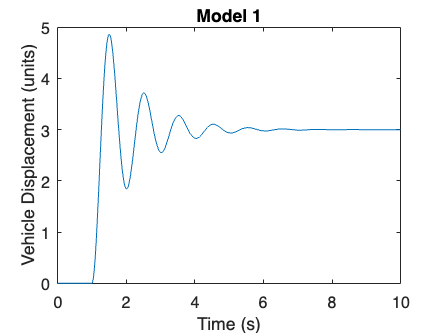

figure()
plot(mass_damper_sim.tout, mass_damper_sim.A)
title('Model 1')
xlabel('Time (s)')
ylabel('Vehicle Displacement (units)')

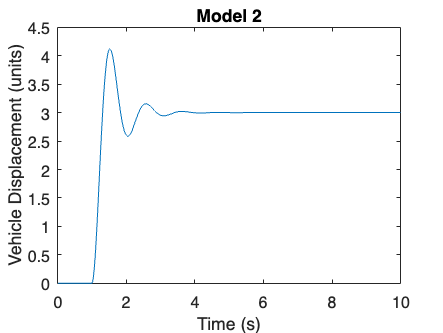


figure()
plot(mass_damper_sim.tout, mass_damper_sim.A1)
title('Model 2')
xlabel('Time (s)')
ylabel('Vehicle Displacement (units)')

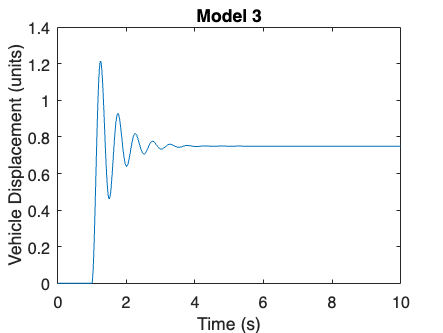

figure()
plot(mass_damper_sim.tout, mass_damper_sim.A2)
title('Model 3')
xlabel('Time (s)')
ylabel('Vehicle Displacement (units)')

### Questions

#### Model 1

Simulated Kss = 3, Calculated Kss = 3

Simulated %OS = 0.6208, Calculated %OS = 0.6209

Simulated Wd = 6.2065 rad/s, Calculated Wd = 6.2121 rad/s

#### Model 2

Doubling the damping ratio should decrease the OS percentage.

Simulated %OS = 0.3723, Calculated %OS = 0.3723

#### Model 3

Doubling the oscilllation frequency should increase speed at which the system reaches steady state. This should be the case because the system should lose energy more rapidly due the the faster oscillations

Model 1 reaches steady state in approx. 7 seconds

Model 3 reaches steady state in approx. 4 seconds

## Exercise 5

Using Simulink to model a PID controller by itself with no plant or feedback.

PID = sim('ME419_EX1_5.slx',10) ; % PID control

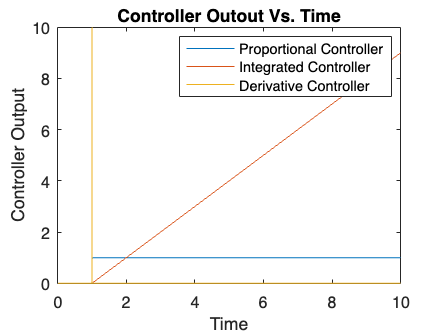

figure()
plot(PID.tout, PID.PControl)
hold on
plot(PID.tout, PID.IControl)
plot(PID.tout, PID.DControl)
ylim([0 10])
ylabel('Controller Output')
xlabel('Time')
title('Controller Outout Vs. Time')
legend('Proportional Controller', 'Integrated Controller', 'Derivative Controller')
hold off

##  Exercise 6

Simulated system with controllers to see how controllers work.

Tank_Control = sim('ME419_EX1_6.slx',60) ; % Tank Control

### Ex 6 Part A - Proportional Only Control

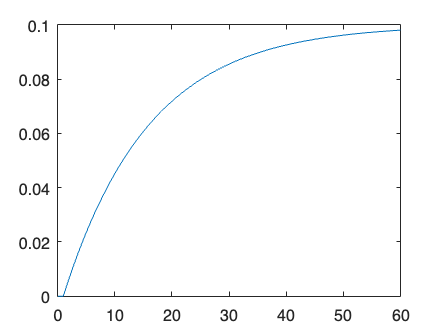

plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_A)

### Ex 6 Part B

figure()
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_B)

### Ex 6 Part C

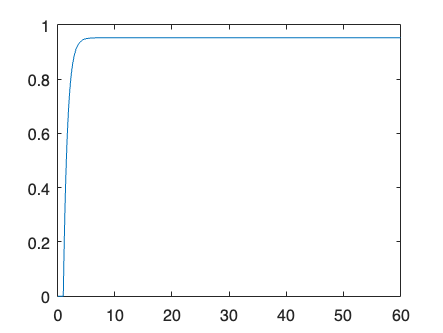

figure()
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_C)

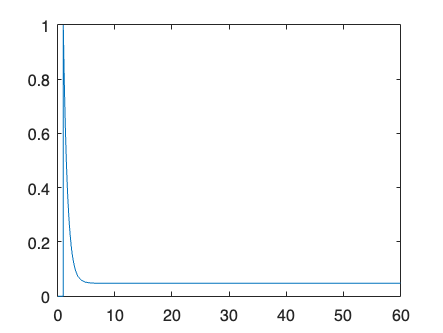

figure()
plot(Tank_Control.tout, Tank_Control.Error_C)

## Ex 1_6 Part D

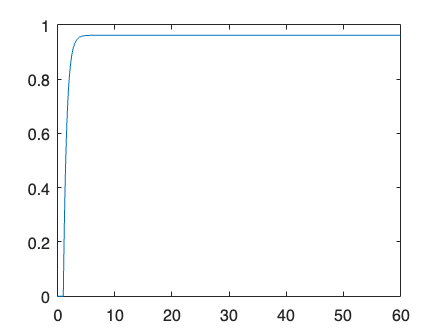

figure() % Output
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_D)

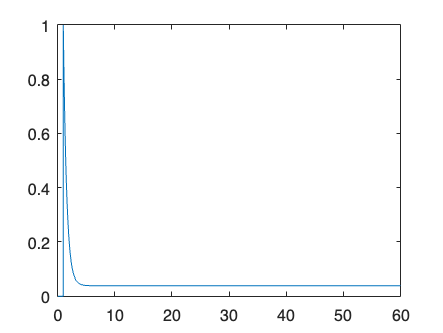


figure() % Error
plot(Tank_Control.tout, Tank_Control.Error_D)